mean_cdata =    1.4404e+06


max_cdata =     4.359e+06


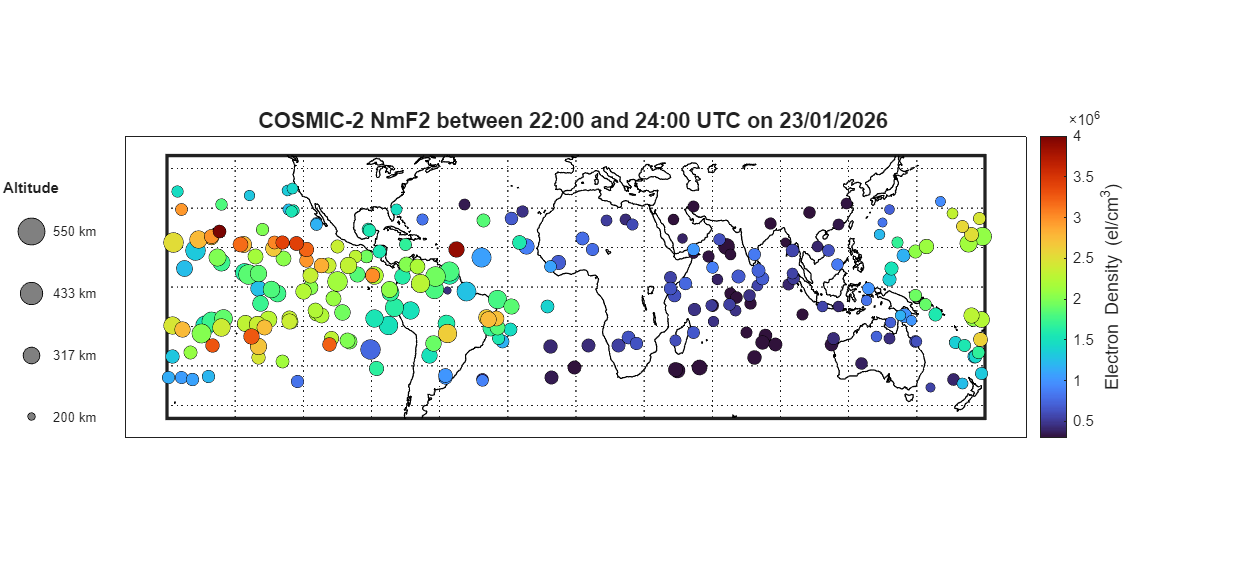

%% COSMIC Electron Density Bubble Map on Globe
% Bubble size = altitude, Bubble colour = electron density
clear min
%% USER PARAMETERS
filter_quartiles  = false; 
lower_pct         = 25;   
upper_pct         = 75;   

% Fixed bounds for bubble size
if strcmp(mission_name, 'ground')
    ALT_MIN = 320;
    ALT_MAX = 350;
else
    ALT_MIN  = 200;   % km
    ALT_MAX  = 550;   % km 
end
SIZE_MIN = 20;   
SIZE_MAX = 260; 

for target_hour = 23
    target_minute  = 00;
    time_tolerance = 60;
    minHour = target_hour-(time_tolerance/60);
    maxHour = target_hour+(time_tolerance/60);

    epoch   = datetime(1980, 1, 6, 0, 0, 0, 'TimeZone', 'UTC');
    all_lat   = [];
    all_lon   = [];
    all_edmax = [];
    all_alt   = [];

    for i = 1:length(COSMIC_data)
        if isnumeric(COSMIC_data{i}.edmaxtime)
            COSMIC_data{i}.edmaxtime = epoch + seconds(COSMIC_data{i}.edmaxtime - 18);
        end

        file_hour            = hour(COSMIC_data{i}.edmaxtime);
        file_min             = minute(COSMIC_data{i}.edmaxtime);
        file_total_minutes   = file_hour * 60 + file_min;
        target_total_minutes = target_hour * 60 + target_minute;

        if abs(file_total_minutes - target_total_minutes) > time_tolerance
            continue
        end

        lat = COSMIC_data{i}.edmaxlat;
        lon = COSMIC_data{i}.edmaxlon;
        ed  = COSMIC_data{i}.edmax;
        alt = COSMIC_data{i}.edmaxalt;

        if isempty(lat) || isempty(lon) || isempty(ed) || isempty(alt), continue; end
        if isnan(lat)   || isnan(lon)   || isnan(ed)   || isnan(alt),   continue; end

        all_lat   = [all_lat;   lat];
        all_lon   = [all_lon;   lon];
        all_edmax = [all_edmax; ed];
        all_alt   = [all_alt;   alt];
    end

    if isempty(all_lat)
        warning('No points found within the time window.');
        continue
    end

    %%Quartile filter
    if filter_quartiles
        q_low  = prctile(all_edmax, lower_pct);
        q_high = prctile(all_edmax, upper_pct);
        keep   = all_edmax >= q_low & all_edmax <= q_high;
        all_lat   = all_lat(keep);
        all_lon   = all_lon(keep);
        all_edmax = all_edmax(keep);
        all_alt   = all_alt(keep);
        fprintf('Hour %02d: kept %d / %d points (%.0f-%.0f pctile)\n', ...
            target_hour, sum(keep), length(keep), lower_pct, upper_pct);
    end

    if isempty(all_lat)
        warning('No points remain after quartile filter for hour %02d.', target_hour);
        continue
    end

    %Normalise altitude drives size
    sz_norm     = (all_alt - ALT_MIN) ./ (ALT_MAX - ALT_MIN);
    sz_norm     = max(0, min(1, sz_norm));  
    bubble_size = SIZE_MIN + sz_norm * (SIZE_MAX - SIZE_MIN)*0.5;
    cdata       = all_edmax;  
    
    %Figure
    figure('Color', 'w', 'Position', [100 100 1000 450]); 
    clf
    axesm('eqdcylin', 'MapLatLimit', [-50 50], 'MapLonLimit', [-180 180], ...
      'Frame', 'on', 'Grid', 'on')

    % Push the map axes right to make room for legend
    set(gca, 'Position', [0.10 0.08 0.78 0.82])
    load coastlines
    geoshow(coastlat, coastlon, 'Color', 'k', 'LineWidth', 0.8)
    hold on

    %Sort by edmax ascending so brightest points plot on top
    [~, sort_idx] = sort(cdata, 'ascend');
    all_lat     = all_lat(sort_idx);
    all_lon     = all_lon(sort_idx);
    bubble_size = bubble_size(sort_idx);
    cdata       = cdata(sort_idx);
    mean_cdata = mean(cdata)
    max_cdata = max(cdata)
    scatterm(all_lat, all_lon, bubble_size, cdata, 'filled', ...
        'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'k', 'LineWidth', 0.3);

    %Colorbar
    colormap("turbo")
    cb = colorbar;
    clim([3e5, 4e6])
    cb.Label.String   = 'Electron Density (el/cm^3)';
    cb.Label.FontSize = 11;
    title(sprintf('COSMIC-2 NmF2 between %02d:%02d and %02d:%02d UTC on %02d/01/2026 ', ...
        minHour, target_minute, maxHour, target_minute, day), ...
        'FontSize', 13, 'FontWeight', 'bold')

    %Altitude size legend
    legend_alts = linspace(ALT_MIN, ALT_MAX, 4);
    legend_sz   = SIZE_MIN + ((legend_alts - ALT_MIN) ./ (ALT_MAX - ALT_MIN)) * (SIZE_MAX - SIZE_MIN);

    leg_ax = axes('Position', [0.00 0.15 0.09 0.55], 'Visible', 'off');
    hold(leg_ax, 'on')

    for k = 1:length(legend_alts)
        scatter(leg_ax, 0.5, k, legend_sz(k), [0.5 0.5 0.5], 'filled', ...
            'MarkerEdgeColor', 'k', 'LineWidth', 0.5)
        text(leg_ax, 0.85, k, sprintf('%d km', round(legend_alts(k))), ...
            'FontSize', 8, 'VerticalAlignment', 'middle')
    end

    text(leg_ax, 0.5, length(legend_alts) + 0.7, 'Altitude', ...
        'FontSize', 9, 'FontWeight', 'bold', 'HorizontalAlignment', 'center')

    xlim(leg_ax, [0 1.8])
    ylim(leg_ax, [0 length(legend_alts) + 1])
    hold off
end


while true; end